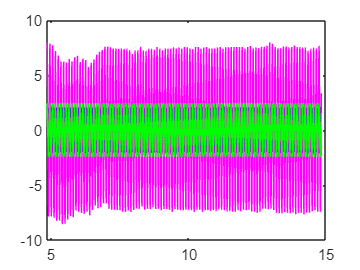

%Atencao
%Rode primeiro o bode_v3
%Esse programa consegue comparar graficamente a resposta
%criada a partir da TF (transfer function)
%obtida da bode_v3 (Output modelo)
%e a resposta coletada no laboratório (Output Real)
%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Somente preencher o q estah escrito aki
% adicionando o arquivo
inputFile = 'sqrf1000a200Ent';
outputFile = 'sqrf1000a200Sai';
int32 np;

%escolhendo a parte de interesse
startTime = 10;
endTime = 11;
np = 4;
%%%%%%%%%%%%%%%%%%%%%%%%%%%

%ajustando os dados para matrizes de tempo e amplitude
input = importdata(inputFile + ".mat");
inputTime = input.([inputFile '_Time']);
inputAmplitude = input.([inputFile '_Value']);

output = importdata(outputFile + ".mat");
outputTime = output.([outputFile '_Time']);
outputAmplitude = output.([outputFile '_Value']);


startIndex = find(inputTime >= startTime, 1);
endIndex = find(inputTime >= endTime, 1);

%gráfico todo
plot(inputTime, inputAmplitude,'b')
hold on;
plot(outputTime, outputAmplitude(:,1),'m',outputTime, outputAmplitude(:,2),'g')
hold off;

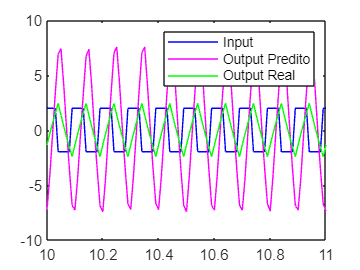


inputTimeRange = inputTime(startIndex:endIndex);
inputAmplitudeRange = inputAmplitude(startIndex:endIndex);

outputTimeRange = outputTime(startIndex:endIndex,:);
outputAmplitudeRange = outputAmplitude(startIndex:endIndex,:);

%gráfico na parte de interesse
plot(inputTimeRange,inputAmplitudeRange,'b')
hold on;
plot(outputTimeRange(:,1),outputAmplitudeRange(:,1),'m')
plot(outputTimeRange(:,2),outputAmplitudeRange(:,2),'g')
legend('Input', 'Output Predito', 'Output Real')
hold off;

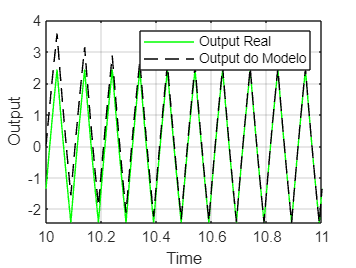

% model_output_teor = lsim(tfTeor, inputAmplitudeRange, inputTimeRange);
model_output_real = lsim(tfReal, inputAmplitudeRange, inputTimeRange);

plot(inputTimeRange, outputAmplitudeRange(:,2), 'g');
hold on
% plot(inputTimeRange, model_output_teor, 'r-');
plot(inputTimeRange, model_output_real, 'black--');
legend('Output Real','Output do Modelo');
xlabel('Time');
ylabel('Output');
grid on
hold off

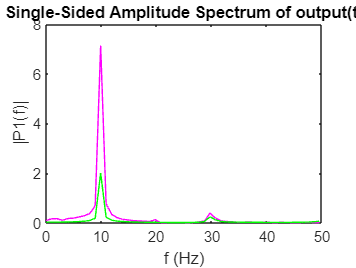

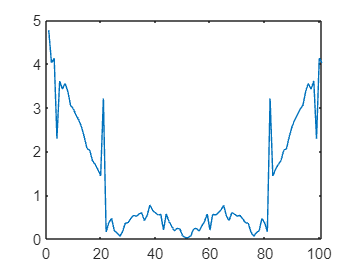

int32 N;
N = length(inputTimeRange);

frequencySample = 1/(inputTimeRange(2) - inputTimeRange(1));
frequencies = frequencySample*(0:(N/2))/N;

inputFft = fft(inputAmplitudeRange);
outputFft = fft(outputAmplitudeRange);

magnitudeResponse = abs(outputFft./inputFft);
phaseResponse = angle(outputFft./inputFft);


P2 = abs(outputFft/N);
P1 = P2(1:floor(N/2)+1,:);
P1(2:end-1) = 2*P1(2:end-1);

plot(frequencies,P1(:,1),'m')
title("Single-Sided Amplitude Spectrum of output(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")
hold on

plot(frequencies,P1(:,2),'g')
hold off